## パス設定

% データリスト読み込み
list = dir('/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/0510/*.csv');
% dataの階層
pl = '/Users/daiki_daiku/Library/CloudStorage/Box-Box/Personal/study/Data/2023/0510/';

## gage設定

g_s = 2108; % 始点位置
% g_e = 2208; % 終点位置
g_e = 3827; % 終点位置
start = 0; % 開始時間
fin = 30.09; % 終了時間
freq = 100; % 周波数
time = linspace(start, 30.09, fin*freq)'; % 時間軸設定
cut = 3; % 切り取る秒数 
Zmax=60

Zmax = 60

Zmin=-3

Zmin = -3

## カラーバーの最大値・最小値、軸、データの設定

for n = 1 : length(list)
    % list(n, 1)に書いてある名前のcsvファイルをreadmatrixで読み込み
    data = readmatrix( [pl list(n).name] );
    if n==1
        % Zmax=Z(1, 1);
        % Zmin=Z(1, 1);
        % Z = data( (start + 6) : (fin - start) * freq + 5, g_s : g_e ); % 計測data
        Z = data( (start + 6) : (fin - start) * freq + 5, g_s : g_e ) .* (-1); % *-1
    else
        Z(:,:,n)=data( (start + 6) : (fin - start) * freq +5, g_s : g_e ) .* (-1);
    end
    % if Zmax<max(max(Z))
    %     Zmax=max(max(Z));
    % end
    % if Zmin>min(min(Z))
    %     Zmin=min(min(Z));
    % end
end

t = ones( fin*freq, g_e - g_s + 1 ) .* time; % 縦軸時間
x = ones( fin*freq, g_e - g_s + 1 ) .* data(5, g_s : g_e); % 横軸位置

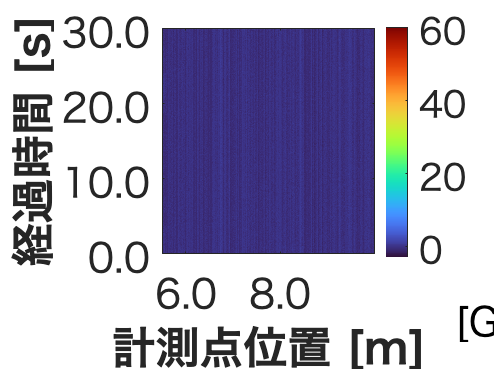

[C,h]=contourf(x, t, Z(:,:,1), LineStyle = "none");
colorbar;
clim( [Zmin Zmax] );
colormap turbo;
xlabel('計測点位置 [m]','FontSize', 25, 'FontWeight', 'bold');
ylabel('経過時間 [s]', 'FontSize', 25, 'FontWeight', 'bold');
% yticks( [0 0.5 1.0 1.5 2.0 2.5 3.0 3.5 4.0 4.5 5.0] );
text=annotation('textbox', [.9 .05 .5 .5],'String', '[GHz]', 'EdgeColor', 'none', 'FontSize', 20);
text.VerticalAlignment = 'bottom';
ytickformat('%.1f');
xtickformat('%.1f');
ax=gca;
set(gca, 'FontSize', 20);

% axis off; % グラフ描画

全体画像

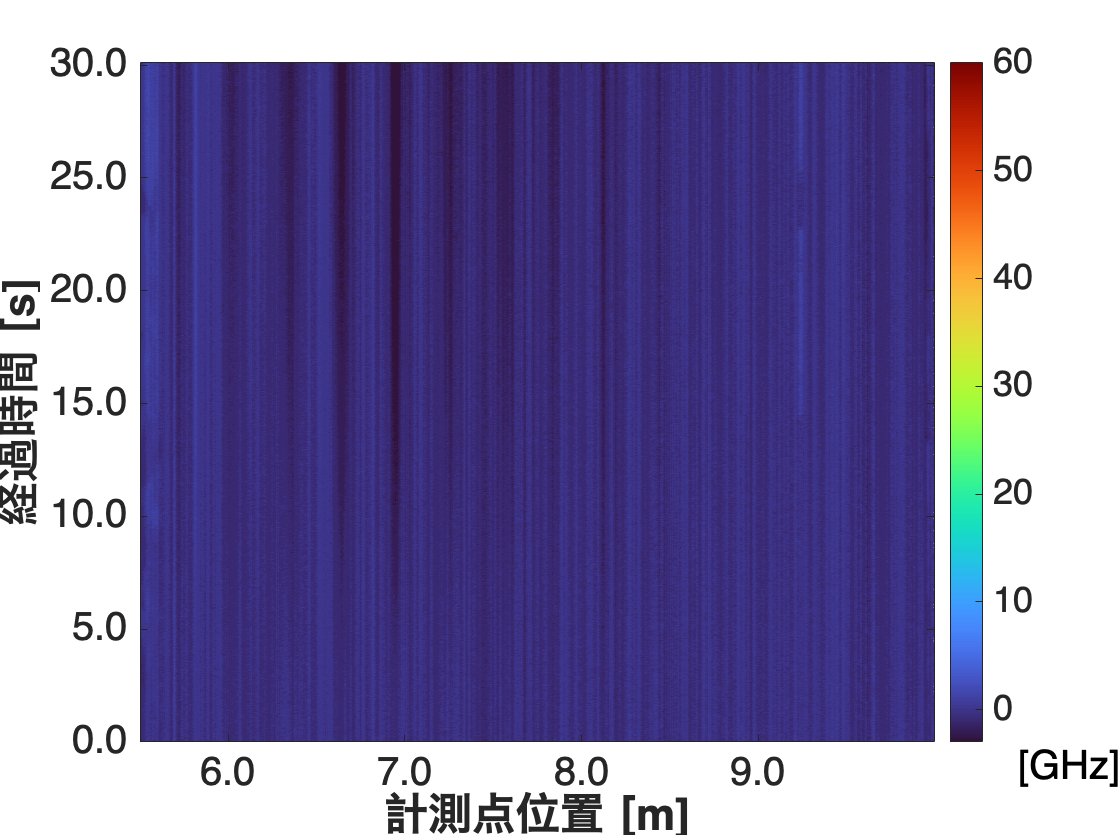

クラス 'Contour' のプロパティ 'ZDataSource' の設定中にエラーが発生しました:
値は文字ベクトルまたは string スカラーでなければなりません。

for n = 1 : length(list)
    % data = readmatrix( [pl list(n).name] ); % list(n,1)に書いてある名前のcsvファイルをreadmatrixで読み込み
    Num = extractBefore( list(n).name, '.csv' );
    % % Z = data( (start + 6) : (fin - start) * freq + 14, g_s : g_e ); % 計測data
    % Z = data( (start + 6) : (fin - start) * freq + 14, g_s : g_e ).*(-1); % 計測data

    % t = ones( size(Z) ) .* time; % 縦軸時間
    % x = ones( size(Z) ) .* data(5, g_s : g_e); % 横軸位置
    
    % H=contourf(x, t, Z, LineStyle = "none"); % グラフ描画
    % ax = gcf;
    % colorbar;
    % colormap turbo;
    % clim( [Zmin Zmax] );
    % xlabel('計測点位置 [m]', 'FontSize', 25, 'FontWeight', 'bold');
    % ylabel('経過時間 [s]', 'FontSize', 25, 'FontWeight', 'bold');
    % yticks( [0 0.5 1.0 1.5 2.0 2.5 3.0 3.5 4.0 4.5 5.0] );
    % t=annotation('textbox', [.9 .05 .5 .5], ...
    % 'String', '[GHz]', 'EdgeColor', 'none', 'FontSize', 20);
    % t.VerticalAlignment = 'bottom';
    % ytickformat('%.1f');
    % xtickformat('%.1f');
    h.ZData=Z(:,:,n);
    % axis off
    filename = append(pl, '分類用画像/raw/' , Num , '.jpg');
    exportgraphics(ax, filename, 'Resolution', 300);
end

## 3秒間隔

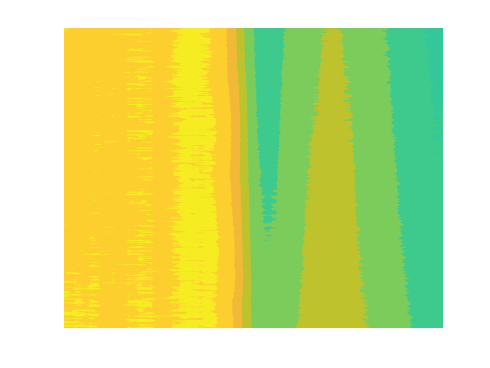

for n = 1 : length(list)
    % list(n, 1)に書いてある名前のcsvファイルをreadmatrixで読み込み
    data = readmatrix( [pl list(n).name] );
    Num = extractBefore( list(n).name,'.csv' );
    Z = data( (start+6) : (fin - start) * freq +14, g_s : g_e ); % 計測data
    for l = 1 : 55
        trim1 = (l - 1) * 50 + 1;
        trim2 = (l - 1) * 50 + cut * 100 - 1;
        z = Z(trim1 : trim2, :);
        t = ones( size(z) ) .* time(trim1 : trim2, :); % 縦軸時間
        x = ones( size(z) ) .* data(5, g_s : g_e); % 横軸位置
        contourf(x, t, z, LineStyle = "none"); % グラフ描画
        colormap turbo
        ax = gcf;
        clim( [Zmin Zmax] );
        axis off
        filename = append(pl, '分類用画像/3秒間隔/', Num, '_', int2str(l), '.jpg');
        exportgraphics(ax, filename, 'Resolution', 300);
    end
end

全体用

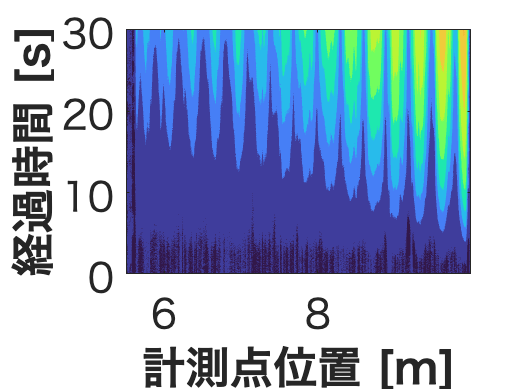

% 
% for n = 1:length(list)
%     %list(n,1)に書いてある名前（n=1のとき1.csv）のcsvファイルをreadmatrixで読み込み
%     data = readmatrix([pl list(n).name]);
%     Num=extractBefore(list(n).name,'.csv');
%     Z = data((start+6):(fin-start)*freq+14,g_s:g_e).*(-1); %計測data
% 
%     contourf(x,t,Z,LineStyle="none"); %グラフ描画
%     ax=gcf;
%     % colorbar
%     colormap turbo
%     clim([Zmin Zmax])
%     xlabel('計測点位置 [m]','FontSize',25,'FontWeight','bold')
%     ylabel('経過時間 [s]','FontSize',25,'FontWeight','bold')
%     set(gca,'FontSize',20)
%     % axis off
%     filename=append(pl,'分類用画像/raw_turbo/' , Num , '.jpg');
%     exportgraphics(ax,filename,'Resolution',300);
% end

% %  zmax=max(Zmax)
% %  zmin=min(Zmin)

## カラーバー

% contourf(x,t,(-1)*Z,LineStyle="none"); %グラフ描画
% fig=gcf;
% colorbar
% colormap turbo
% zmax=-1*zmax
% zmin=-1*zmin
% clim([Zmax Zmin])
% set(gca,'FontSize',20)